Companion software for "Volker Ziemann, *Physics and Finance, Springer, 2021*" ([https://link.springer.com/book/10.1007/978-3-030-63643-2](https://link.springer.com/book/10.1007/978-3-030-63643-2))

# Controlling the Robinson-Crusoe economy (Section 11.7)

Volker Ziemann, 211116, CC-BY-SA-4.0

In this example we use an LQR-controller in order to stabilize a Robinson-Crusoe economy, whose equilibrium is slightly perturbed. 

We start by making a few symbols` global `and define the parameters of the simulation. Here `lambda` is the productivity level of the economy, `delta` the depreciation of the capital `k`, and `Theta` the parameter of a Cobb-Douglas production function. The evolution of the economy is then given by Equation 11.59.

clear all
global a b gain
Theta=0.7;
lambda=1;
delta=0.2;

In the following lines we specify a desired profit level` pbar` in equilibrium and, by solving Equation 11.59 for $\dot k=0$, we find the equilibrium level of the capital `kbar.`

pbar=1.9314;                           % desired profit level in the book
g=@(k)lambda.*k.^Theta-delta.*k-pbar;  % Eq.11.59 at equilibrium
kbar=fzero(g,2*pbar)                   % equilibrium capital 

kbar = 4.3611

The evolution equation for the Robison-Crusoe economy, linearized around the stable fixed point, leads to $\dot x = a x + bu$, where the coefficients $a$ and $b$ are given in Equation 11.60. Here $x$ is the deviation from `kbar` and $u$ is the deviaton from equilibrium profit level `pbar`, which is the same as an increased investment rate and is the parameter we use to control our system.

a=Theta*lambda*kbar^(Theta-1)-delta   

a = 0.2500

b=-1

b = -1

The parameters q and r are the weights from Equation 11.61 and define whether, after a perturbation of the economy, we are eager to quickly return back to the equilibrium ( $q \gg r$ ) or whether we want to maintain a constant level of profits  ( $r \gg q
$ ), which will make the shareholder happy.

q=1;  % weights for the LQR regulator
r=5;

The gain `Kgain_p` for the costate controller is given by the solution of the stationary Riccati equation from Equation 11.58, which  leads to the` gain` of the feedback, which is given in Equation 11.62. Once we have the feedback specified, we simulate the slightly perturbed system with the numerical integrator ode45(), where the differential equation is specified by the function fun() that is defined in the Appendix.

Kgain_p=(a*r/b^2)*(1+sqrt(1+(q*b^2)/(r*a^2)))

Kgain_p = 3.8118

gain=-(b/r)*Kgain_p

gain = 0.7624

x0=-0.1;                        % initial perturbation of x (or the capital k)
[t,x]=ode45(@fun,[0 10], x0);

The numerical integrator returns the time and state variable x, which we plot. The controller value u follows from Equation 11.62 and is also plotted in the same graph.

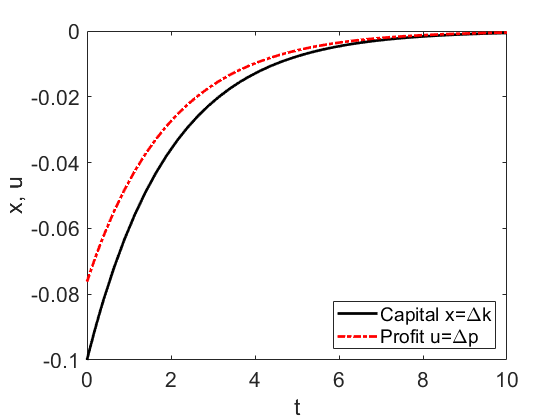

plot(t,x,'k',t,gain*x,'r-.','LineWidth',2)
xlabel('t'); ylabel('x, u')
legend('Capital x=\Deltak','Profit u=\Deltap','Location','SouthEast')
set(gca,'Fontsize',16)

With $r \gg q
$ you see that the profits recover more quickly and  with $q \gg r$ the capital recovers more quickly.

## Appendix

The function` fun()` receives the time `t` and state variable `x` as input and returns the right-hand side of the differential equation $\dot x = a x + bu$. Internally, it calculates the controller gain `u` from the state variable and the feedback gain.

function dxdt=fun(t,x)
global a b gain
u=gain*x;          % apply the feedback law
dxdt=a*x+b*u;      % calculate derivative
end